clc
clear
close all


## setting the scene

% row, column obstacle rate definition 
rows = 10;
cols = 20;
obsRate = 0.3;
[field, cmap] = defColorMap(rows, cols, obsRate)

field =      2     1     2     2     1     1     2     1     2     2     2     2     1     1     1     1     1     1     1     1
     1     2     2     1     1     1     1     1     2     1     2     2     1     2     1     1     1     1     2     1
     1     1     2     1     1     1     1     2     1     1     1     1     1     2     1     2     1     2     1     1
     2     1     1     1     2     1     1     2     1     1     2     1     2     2     1     2     1     2     2     1
     1     1     2     2     1     2     1     1     1     1     2     2     1     2     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     2     1     1     1     1     1     1     1     1
     1     2     1     1     1     1     1     1     1     1     2     1     1     2     1     1     2     1     1     1
     1     1     1     1     2     1     1     1     2     1     1     2     1     1     1     1     2     1     2     2
     1     1     2     1

cmap =      1     1     1
     0     0     0
     1     0     0
     1     1     0
     1     0     1
     0     1     0
     0     1     1



%setting the starting position and goal position
startPos=2;
goalPos = rows*cols -2

goalPos = 198

field(startPos) = 4;
field(goalPos) = 5;


## initialization

U(:, 1) =(1:rows*cols); %the first columns is node no.
U(:, 2) = inf; % the second columns of U records the current shortest path from the starting position
S = [startPos, 0]; % record the shortest path from the starting position to current position
U(startPos, :) = [];


## update the neighbour nodes with their distance away from the starting position

neighborNodes = getNeighborNodes(rows, cols, startPos, field);
for i =1:8
    childNode = neighborNodes(i,1);
    
    if ~isinf(childNode)
        idx = find(U(:,1) == childNode);
        U(idx,2) = neighborNodes(i,2);
    end
end

% best path set in S
for i = 1:rows*cols
    path{i,1} = i;
end
for i = 1:8
    childNode =  neighborNodes(i,1);
    if ~isinf(neighborNodes(i,2))
        path{childNode,2} = [startPos,neighborNodes(i,1)];
    end
end


## recursion

while ~isempty(U)
    
    % 在U集合找出当前最小距离值的节点,视为父节点，并移除该节点至S集合中
    [dist_min, idx] = min(U(:,2));
    parentNode = U(idx, 1);
    S(end+1,:) = [parentNode, dist_min];
    U(idx,:) = [];
    
    % 获得当前节点的临近子节点
    neighborNodes = getNeighborNodes(rows, cols, parentNode, field);

    % 依次遍历邻近子节点，判断是否在U集合中更新邻节点的距离值
    for i = 1:8
        
        % 需要判断的子节点
        childNode = neighborNodes(i,1);
        cost = neighborNodes(i,2);
        if ~isinf(childNode)  && ~ismember(childNode, S)
            
            % 找出U集合中节点childNode的索引值
            idx_U = find(childNode == U(:,1));            
            
            % 判断是否更新
            if dist_min + cost < U(idx_U, 2)
                U(idx_U, 2) = dist_min + cost;
                
                % update 
                path{childNode, 2} = [path{parentNode, 2}, childNode];
            end
        end
    end
end


## draw raster map

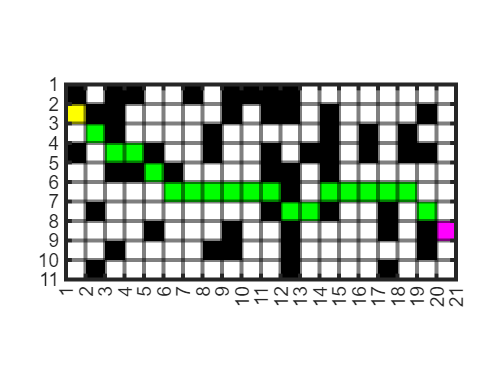


% optimal path
path_opt = path{goalPos,2};
field(path_opt(2:end-1)) = 6;

% draw raster map
image(1.5,1.5,field);
grid on;
set(gca,'gridline','-','gridcolor','k','linewidth',2,'GridAlpha',0.5);
set(gca,'xtick',1:cols+1,'ytick',1:rows+1);
axis image;